# Homework 4

**Problem 0. **Download the .mat file 

file = load('Homework4.mat');

**Problem 1. **The`data1` variable contains 1,000 data points, and the `regressors1` variable contains 100 regressors that might explain these data points. (Note: a constant regressor is already included as the 100th regressor.) Consider a linear model that attempts to predict the data as a weighted sum of the regressors. Apply this model to the data, using bootstrapping (500 iterations) to obtain 95% confidence intervals on the parameters of the model. Visualize these confidence intervals on a figure.

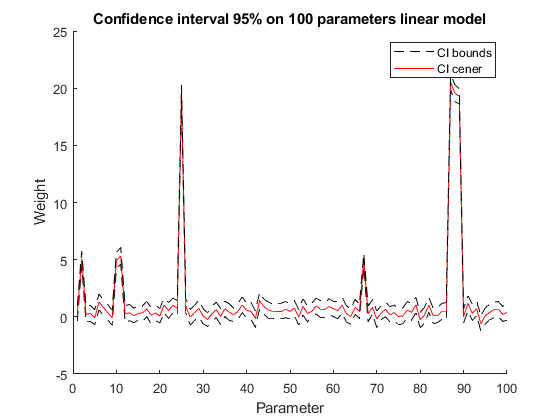

% Bootstrap samples number
numboots = 500;
data = file.data1;
regs = file.regressors1;

% 500 bootstraps, 100 regressors
weights = zeros(500,100);

for i = 1:numboots
    bootidx = ceil(length(data)*rand(1,length(data)));
    X = regs(bootidx,:);
    weights(i,:) = inv(X'*X)*X'*data(bootidx);
end

% Now take the confidence interval of 95%. It means, that from the obtained
% weights only weights between 2.5 and 97.5 percentiles are token. 50
% percentile is for the center line.
confweights = prctile(weights,[2.5 50 97.5], 1);

figure; hold on;
lb = plot(confweights(1,:), 'k--');
c = plot(confweights(2,:), 'r-');
ub = plot(confweights(3,:), 'k--');
xlabel('Parameter');
ylabel('Weight');
title('Confidence interval 95% on 100 parameters linear model');
legend([lb, c], 'CI bounds', 'CI center')
hold off;

**Problem 2. **We have 20 subjects and 100 measurements of *x *and *y* from each subject. The `xdata` variable contains the *x*-measurements, and the `ydata `variable contains the *y*-measurements. We want to see whether there is a nonlinear (quadratic) relationship between the *x* variable and the *y *variable. To do this, for each subject, use 10-fold cross-validation to estimate (1) the accuracy of a linear model (*y* = *ax* + *b*) and (2) the accuracy of a quadratic model (*y *=* ax*2 +* bx *+* c*). Use* R*2 to quantify accuracy. Make a scatter plot that compares the accuracy of the linear model and the accuracy of the quadratic model (there should be 20 dots on this scatter plot).

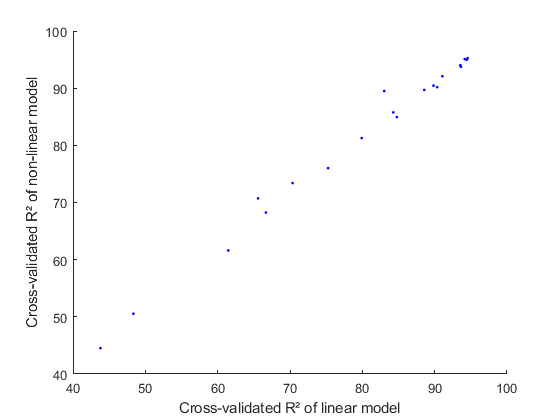

x = file.xdata;
y = file.ydata;

%k-fold validation for k=10
k = 10;
mixed = randperm(length(x));
numingroup = ceil(length(x)/10);
mixed = reshape([mixed NaN(1,k*numingroup-length(x))],k,numingroup);

lpreds = zeros(k, numingroup);
qpreds = zeros(k, numingroup);

subjects = size(x,2);
points = size(x,1);

R2l = zeros(1, subjects);
R2q = zeros(1, subjects);

computeR2 = @(model,data) 100 * (1 - sum((data-model).^2) / sum((data-mean(data)).^2));

for subject=1:subjects
    lpred = zeros(points,1);
    qpred = zeros(points,1);
    for i = 1:k
        testix = mixed(i,:);
        testix(isnan(testix)) = [];
        trainix = setdiff(1:length(x), testix);
        
        % Construct regressors on data, splitting it according to 10-fold
        trainx = [x(trainix, subject) ones(length(trainix),1)];
        trainy = y(trainix, subject);
        testx = [x(testix, subject) ones(length(testix),1)];
        testy = y(testix, subject);
        
        % Calculate weights and predict on test data
        wl = inv(trainx'*trainx)*trainx'*trainy;
        lpred(testix) = testx*wl;
        
        % Repeat these actions for non-linear model
        trainx = [x(trainix, subject).^2 x(trainix, subject) ones(length(trainix),1)];
        testx = [x(testix, subject).^2 x(testix, subject) ones(length(testix),1)];
        wq = inv(trainx'*trainx)*trainx'*trainy;
        qpred(testix) = testx * wq;
    end
    % Compute the R² values for both models' predictions
    R2l(subject) = computeR2(lpred, y(:,subject));
    R2q(subject) = computeR2(qpred, y(:,subject));
end

% Visualize R²'s

figure; hold on;
scatter(R2l, R2q, 'b.');
xlabel('Cross-validated R² of linear model');
ylabel('Cross-validated R² of non-linear model');